# Simulation of the 3D contribution

Every parameter in this program is in SI units.

clear; close all;

## Parameters

Physical parameters

global l;
l = 1000e-6; % Wavelength
global Ns;
Ns = 1.45; % Silica idex
global Na;
Na = 1; % Air index (for later)

Laser parameters

global On;
On = 4e-1; % Numerical aperture
global w0;
w0 = 3e-6; % Waist
global M;
M = sqrt(pi*w0^2*On/l); % Square root of the beam-quality factor
global zr;
zr = w0/On; % Rayleigh distance

Fiber parameters

global R;
R = 62.5e-6; % Curvature radius
global zi;
zi = -20e-6;  % Position of the interface
global zmax;
zmax = zi + R; % Radius of the fiber

Numerical parameters

global res;
res = 1e-6; % Numerical resolution
global x_window_width;
x_window_width = 64;
global y_window_width;
y_window_width = 64;

Inline functions

global q;
q = @(z) z + 1i*zr; % Inline function to compute the Complex beam parameter
global w;
w = @(z) w0*sqrt(1+(z/z(1,1)^2)); % Inline function to compute the Gaussian beam width

## Simulations

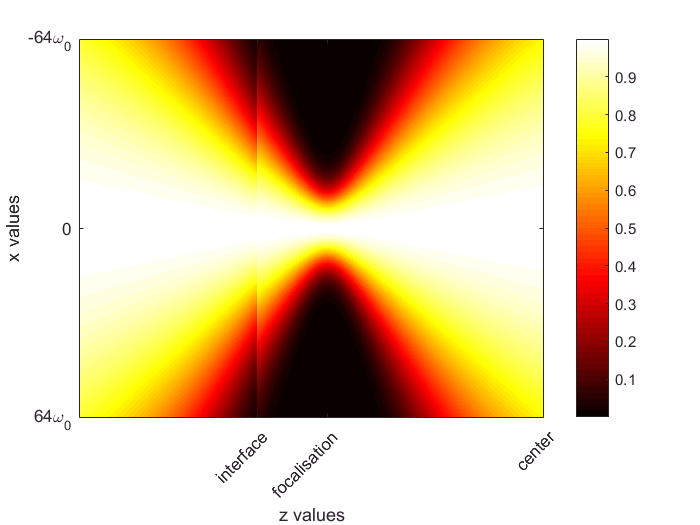

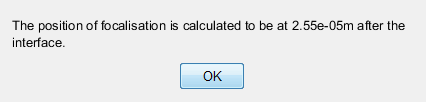

calcul_x;

calcul_y;

Undefined function or variable 'q'.

Error in calcul_y (line 38)
Q(1,1) = feval(q,z(1,1)); % Initialization of the first value
